# **디지털신호처리 ****HW#2**

Due date : 2021.12.22. 23:59

**이름**** : 박수영 **

**학번**** : 201910941**

아래 문제에 대하여 MATLAB으로 구현하고 mlx파일을 본인의 Github에 업로드 하고 링크 주소를 적으세요.

**Repository 링크 : **

1. 이산 비주기 신호 $x\left\lbrack n\right\rbrack =\left\lbrace \underset{\uparrow }{1} ,2,2,1\right\rbrace$에 대하여 다음을 구하라.

1) 4점 DFT 및 IDFT를 수행하라. 그리고 DFT의 결과를 DTFT와 비교하라. 

x = [1,2,2,1];
N = 4;
X = dft(x,N);
magX1 = abs(X), phaX1 = angle(X)*180/pi

magX1 =     6.0000    1.4142    0.0000    1.4142


phaX1 =          0 -135.0000  -90.0000  135.0000


xn1 = idft(X,N)

xn1 =    1.0000 - 0.0000i   2.0000 - 0.0000i   2.0000 + 0.0000i   1.0000 + 0.0000i


2) 영 채우기를 시행하여 같은 신호에 대해 16점 DFT 및 IDFT를 수행하라.

x = [1,2,2,1, zeros(1,12)];
N = 16;
X = dft(x,N);
magX2 = abs(X), phaX2 = angle(X)*180/pi

magX2 =     6.0000    5.5861    4.4609    2.9357    1.4142    0.2607    0.3170    0.3308    0.0000    0.3308    0.3170    0.2607    1.4142    2.9357    4.4609    5.5861


phaX2 =          0  -33.7500  -67.5000 -101.2500 -135.0000 -168.7500  -22.5000  -56.2500   90.0000   56.2500   22.5000  168.7500  135.0000  101.2500   67.5000   33.7500


xn2 = idft(X,N)

xn2 =    1.0000 + 0.0000i   2.0000 + 0.0000i   2.0000 - 0.0000i   1.0000 - 0.0000i   0.0000 - 0.0000i   0.0000 - 0.0000i   0.0000 - 0.0000i   0.0000 - 0.0000i   0.0000 - 0.0000i   0.0000 - 0.0000i   0.0000 - 0.0000i  -0.0000 - 0.0000i  -0.0000 - 0.0000i  -0.0000 - 0.0000i  -0.0000 - 0.0000i  -0.0000 - 0.0000i


2. (P5.2) DFS의 정의를 사용하여 다음 주기 신호의 DFS 계수를 구하고, MATLAB을 사용하여 검증하라.

1) $\tilde{x_1 } \left(n\right)=\left\lbrace 4,1,-1,1\right\rbrace ,N=4$

Xtilde1 = [4,1,-1,1];
N = 4;
xtiled1 = dfs(Xtilde1,N)

xtiled1 =    5.0000 + 0.0000i   5.0000 + 0.0000i   1.0000 - 0.0000i   5.0000 + 0.0000i


2) $\tilde{x_2 } \left(n\right)=\left\lbrace 1,0,-1,-1,0\right\rbrace ,N=5$

Xtiled2 = [1,0,-1,-1,0];
N = 5;
xtiled2 = dfs(Xtiled2,N)

xtiled2 =   -1.0000 + 0.0000i   2.6180 + 0.0000i   0.3820 - 0.0000i   0.3820 + 0.0000i   2.6180 + 0.0000i


3.  (P5.10) 아래와 같이 주어진 유한 길이 신호를 고려하자.


$$x\left(n\right)=\left\lbrace \begin{array}{ll}
{\textrm{sinc}}^2 \left\lbrace \frac{\left(n-50\right)}{2}\right\rbrace  & 0\le n\le 100\\
0 & \textrm{otherwise}
\end{array}\right.$$


1) x(n)의 DFT X(k)를 구하라. (stem 함수를 사용하여) 그것의 크기 및 위상 그래프를 그려라. 

n = 0:100;
xn = sinc((n-50)/2).^2;
N = length(xn);
Xk = dft(xn,N);
k = 0:N-1;
mag_Xk = abs(Xk);
pha_Xk = angle(Xk)*180/pi;

Hf_1 = figure;
set(Hf_1,'NumberTitle','off','Name','P5.8');
subplot(2,1,1);
H_s1 = stem(k,mag_Xk,'filled');
set(H_s1,'markersize',3);
axis([0,N,0,2.5]);
ylabel('Magnitude');

subplot(2,1,2);
H_s2 = stem(k,pha_Xk,'filled');
set(H_s2,'markersize',3);
xlabel('k');
ylabel('Degrees');

2) MATLAB을 사용하여 x(n)의 DTFT $X\left(e^{j\omega } \right)$의 크기 및 위상 그래프를 그려라.

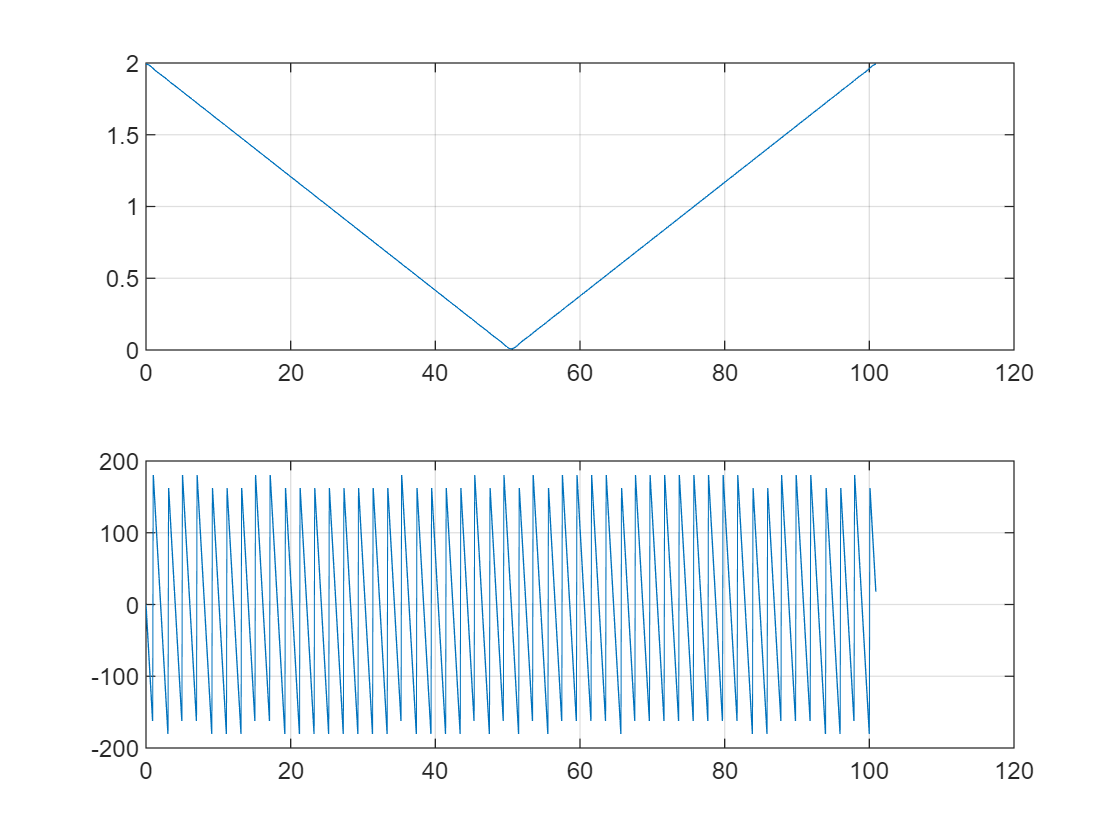

[X,w] = freqz(xn,1,1000,'whole');
mag_X = abs(X);
pha_X = angle(X)*180/pi;
Dw = (2*pi)/N;
subplot(2,1,1);
plot(w/Dw,mag_X); grid
subplot(2,1,2);
plot(w/Dw,pha_X); grid

3) 위 DFT는 $X\left(e^{j\omega } \right)$의 샘플링된 변형임을 검증하라. hold 함수 (hold on;) 를 사용해서 두 그래프를 합치도록 한다.

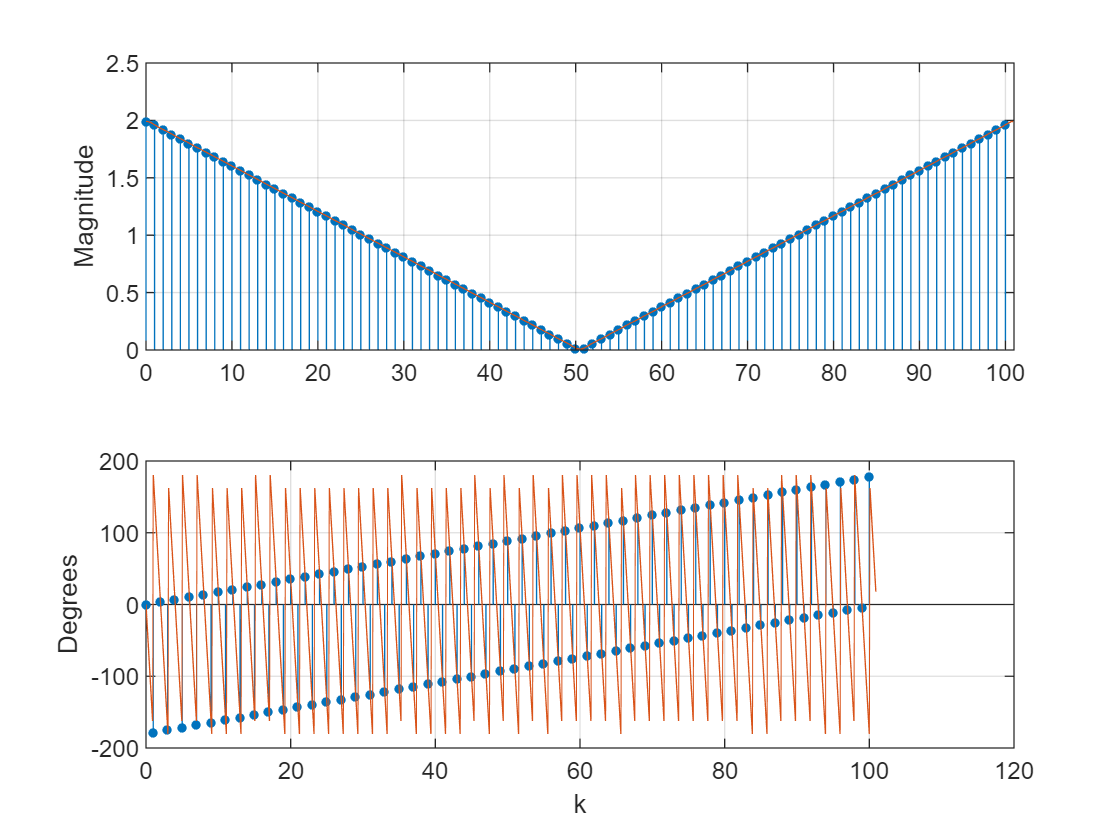

n = 0:100;
xn = sinc((n-50)/2).^2;
N = length(xn);
Xk = dft(xn,N);
k = 0:N-1;
mag_Xk = abs(Xk);
pha_Xk = angle(Xk)*180/pi;

Hf_1 = figure;
set(Hf_1,'NumberTitle','off','Name','P5.8');
subplot(2,1,1);
H_s1 = stem(k,mag_Xk,'filled');
set(H_s1,'markersize',3);
axis([0,N,0,2.5]);
ylabel('Magnitude');
hold on
subplot(2,1,2);
H_s2 = stem(k,pha_Xk,'filled');
set(H_s2,'markersize',3);
xlabel('k');
ylabel('Degrees');
hold on

[X,w] = freqz(xn,1,1000,'whole');
mag_X = abs(X);
pha_X = angle(X)*180/pi;
Dw = (2*pi)/N;
subplot(2,1,1);
plot(w/Dw,mag_X); grid
subplot(2,1,2);
plot(w/Dw,pha_X); grid

function [Xk] = dft(xn,N)
n = [0:1:N-1];
k = [0:1:N-1];
WN = exp(-j*2*pi/N);
nk = n'*k;
WNnk = WN .^ nk;
Xk = xn * WNnk;
end

function [xn] = idft(Xk,N)
n = [0:1:N-1];
k = [0:1:N-1];
WN = exp(-j*2*pi/N);
nk = n'*k;
WNnk = WN .^ (-nk);
xn = (Xk * WNnk)/N;
end

function [Xk] = dfs(xn,N)
n = [0:1:N-1];
k = [0:1:N-1];
WN = exp(-j*2*pi/N);
nk = n'*k;
WNnk = WN .^ nk;
Xk = xn * WNnk;
end

4) DFT $X\left(k\right)$로부터 DTFT $X\left(e^{j\omega } \right)$를 재구성할 수 있는가? 가능하다면, 재구성에 필요한 보간 공식을 구하라. 가능하지 않다면, 그 이유를 기술하라.

-DFT의 길이가 x(n)의 길이보다 크거나 같으면 DFT X(k)로부터  DTFT를 재구성할 수 있다. 

-보간공식: X(e^jw) = sigma(k=0 ~ N-1) X(k)*pi(w-2*pi*k/N), pi(w) = e^-jw(N-1)/2 * {sin(wN/2) / Nsin(w/2)} 으로 

 N=101이기 때문에 X(e^jw) = sigma(k=0 ~ 100) X(k)*e^-j(50)w * {sin(50.5w) / 101sin(w/2)}